## Problem 1

In lecture and homework we explored how the convolution can be used to  calculate the probability of a sum or average. For this problem we are  going to imagine that we are looking for gamma-ray sources (e.g. with  the [Fermi telescope](https://fermi.gsfc.nasa.gov)). In this  kind of telescope there is a background of cosmic-rays (electrons and  protons, mostly) that provides a discrete noise term across the sky that precisely follows a Poisson distribution. To detect a gamma-ray source, you need to ask what is the probability that the cosmic-ray background  would have given you a measurement as signal-like or more than the  signal that you received.

To set up the problem, assume in 1 day the average cosmic-ray  background is some number X (pick someting btwn 0.5 and 10, with  different values for you and your lab partner); and the average number  of gamma-rays emitted by your hypothetical source is Y (pick something  larger than X).

A) Show how the probability distribution of the background changes as you integrate (sum) for more days.

For this problem I am assuming an average background count of $X=4$ with the average number of gamma-rays emitted by the source of $Y=8$. 

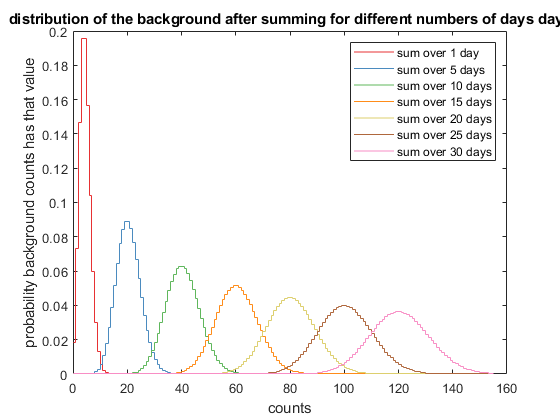



oneday_background_average = 4;
oneday_background = makedist('Poisson', 'lambda', oneday_background_average);

max_day_number = 30;
multi_day_array = 5:5:max_day_number;
xmax = 100*oneday_background_average;
multi_day_sumpdf_array = zeros(length(multi_day_array), multi_day_array(end)*xmax);


single_day_dist = makedist('Poisson', 'lambda', oneday_background_average);
x = 0:xmax;
single_day_pd = pdf(single_day_dist, x);

for i = 1:length(multi_day_array)
    
    days = multi_day_array(i);
    
    multi_day_pdf = single_day_pd;
    
    for j = 2:days
        
        multi_day_pdf = conv(multi_day_pdf, single_day_pd);
        
    end
    
    multi_day_sumpdf_array(i+1, 1:days*xmax+1) = multi_day_pdf;

end

multi_day_sumpdf_array(1,1:xmax+1) = single_day_pd;

Colors = linspecer(length(multi_day_array) +  1);

sum_x_plot_max = 1.3*oneday_background_average*multi_day_array(end)-1;
x_plot_range = 0:sum_x_plot_max;
x_plot_index_range = x_plot_range+1;

for i = 1:length(multi_day_array)+1
    stairs(x_plot_range,multi_day_sumpdf_array(i,x_plot_index_range), 'Color', Colors(i, :))
    hold on
end
datacursormode on
title(['distribution of the background after summing for different numbers of days days'])
xlabel('counts')
ylabel('probability background counts has that value')
labels = cell(1,length(multi_day_array)+1);
for i = 1:length(multi_day_array)+1
    if i == 1
        string = ['sum over ' num2str(i) ' day'];
    else
        string = ['sum over ' num2str(multi_day_array(i-1)) ' days'];
    end
    labels{i} = string;
end

legend(labels)

As we add together the signal for multiple days, the average understandably increases. Also, the distribution spreads out as we increase the total number of days summed over. This decreases the value at the peak of the pdf for the summed distributions. The distributions also seem more and more symmetric about their means at a larger number of summed days. 

B) Show that after 5 days, the summed probability distribution is still a Poisson distribution. Explain why this makes sense from a mathematical and conceptual point of view.

Conceptually: The poisson distribution for our single day describes the distribution of values expected after measuring over a single day. Because there is only one parameter, the mean $X = 4$, we can think of the entire background described as: Poisson distributed with an average of 4 counts per day.  The background distribution is still Poisson if counted over an hour, a minute, a week, or a year. It can't tell how long you're taking data for. The only thing that changes is the expected number of mean counts. And if you divided back out by the number of days, you would expect to still have 4 counts per day. 

Mathematically: The sum of two independent poisson distributions with means $\lambda_1, \lambda_2$ is a third poisson distribution with mean $\lambda = \lambda_1 + \lambda_2$. 

Let two poisson distributions, $X$ and $Y$ be given with means listed above. Constructing a random variable $Z$ by taking the sum of a value pulled from $X$ and a value pulled from $Y$ gives the following probability distribution of $Z$:


$$P(Z = z) = \sum_{n = 0}^{z} P(X = n) \times P(Y = z-n) = \sum_{n = 0}^{z} \frac{e^{-\lambda_1} \lambda_1^n}{n!} \times \frac{e^{-\lambda_2} \lambda_2^{z-n}}{(z-n)!} = e^{-(\lambda_1 + \lambda_2)} \sum_{n = 0}^{z} \frac{ \lambda_1^n \lambda_2^{(z-n)}}{(z-n)!n!}$$
 

We can notice the similarity in the sum to the expression $(\lambda_1 + \lambda_2)^z$ being written out term by term and insert the $z! / z!$ necessary to complete it:


$$P(Z = z) = e^{-(\lambda_1 + \lambda_2)} \sum_{n = 0}^{z} \frac{ \lambda_1^n \lambda_2^{(z-n)}}{(z-n)!n!} = \frac{ e^{-(\lambda_1 + \lambda_2)}}{z!} \sum_{n = 0}^{z} \lambda_1^n \lambda_2^{(z-n)} \frac{z! }{(z-n)!n!} = \frac{ e^{-(\lambda_1 + \lambda_2)}}{z!} \sum_{n = 0}^{z} \lambda_1^n \lambda_2^{(z-n)} {z \choose n} =  \frac{ e^{-(\lambda_1 + \lambda_2)}}{z!} (\lambda_1 + \lambda_2)^z = \frac{e^{-\lambda} \lambda^z}{z!}$$


Because the sum of any two independent poisson distributions is Poisson, by the associative property of addition, the sum of any number of independent poisson distributions is a poisson distribution. So, the sum of our 5 daily poisson distributions is still a poisson distribution.

C) Show how the  probability distribution evolves as you *average* days. Calculate for many different ranges of days, and explore the shape of the distribution as the number of days becomes larger. Discuss this in relation to both B) and the central limit theoem.

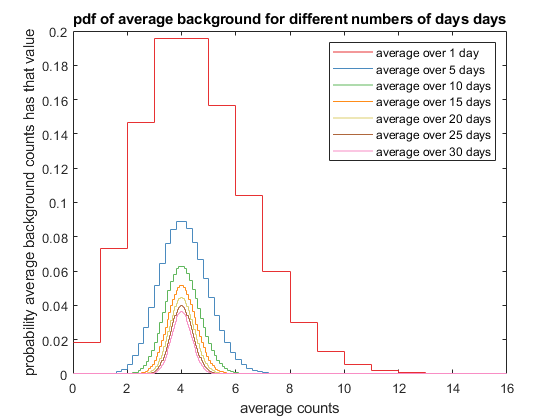

max_x_val = 4*oneday_background_average;
x_plot_range = 0:max_x_val;
x_plot_index_range = x_plot_range+1;


figure

for i = 1:(length(multi_day_array)+1)
    if i == 1
        x_plot_range = 0:1:max_x_val;
        x_plot_index_range = round(i*x_plot_range)+1;
        stairs(x_plot_range,multi_day_sumpdf_array(i,x_plot_index_range), 'Color', Colors(i, :))
        hold on
    else
        x_plot_range = 0:1/multi_day_array(i-1):max_x_val;
        x_plot_index_range = round(multi_day_array(i-1)*x_plot_range)+1;
        stairs(x_plot_range,multi_day_sumpdf_array(i,x_plot_index_range), 'Color', Colors(i, :))
        hold on
    end
end
xlim([0,max_x_val])
datacursormode on
title(['pdf of average background for different numbers of days days'])
xlabel('average counts')
ylabel('probability average background counts has that value')

labels = cell(1,length(multi_day_array)+1);
for i = 1:length(multi_day_array)+1
    if i == 1
        string = ['average over ' num2str(i) ' day'];
    else
        string = ['average over ' num2str(multi_day_array(i-1)) ' days'];
    end
    labels{i} = string;
end

legend(labels)

Similarly to in part B), the probability distributions as we average longer and longer seem to shrink down. Again this comes from the probability being spread out over more and more points. Because we are taking the average, however, the mean value does not change, seen by the peak location not moving. Finally, we again see the distribution becoming more symmetric. In addition to becoming more symmetric, it is more and more shaped like a normal distribution. We expect this from the central limit theorem: "when independent random variables are added, their properly normalized sum tends towards a normal distribution". Particular to averaging identical random variables together, from the CLT we expect the variance of this distribution to decrease relative to the mean with an increasing number of averages. We demonstrated this for averaging normal distributions in hw2. Taking a sum (or average) of a large number of poisson distributions, we could group them in large enough groups that the pdf of their subgroups was well approximated by a normal distribution, and then take the result we showed in hw2 to show that this decreasing variance holds true for the poisson distribution as well.

D) Pick some number of days N, and assume you saw Y*N gamma rays from your source. Calculate the 'sigma' of your observation. [In reality the number of gamma-rays seen from a source will also fluctuate, but we're going to ignore that complication for a couple of labs.]

Suppose that after $N = 10$ days we saw $Y*N = 80$ gamma rays from our source. Using the result from part B), we know that our background distribution over these 10 days will be Poisson distributed with a mean value of $N*X =40$. To calculate a 'sigma' for this observation we first calculate the probability that a count of 80 or greater would be counted from just the background. Note that using poisscdf(x, mean) includes the probability of values less than or equal to the point. 

number_days = 10;
background_mean = oneday_background_average*number_days;

source_counts_per_day = 8;
source_counts_over_days = number_days*source_counts_per_day;

prob_background_less_than_source = poisscdf(source_counts_over_days-1, background_mean);
prob_background_at_least_as_much = 1 - prob_background_less_than_source;

sigma_val = norminv(1-prob_background_at_least_as_much)

sigma_val =    5.519950908032288


Giving us a sigma value of 5.5, a detection! Note that this is the sigma value associated with the probability that we would measure a count of 80 or more gamma rays over 10 days of measurement, if there was no source. 

## Problem 2

Pick a skewed continuous distribtuion, such as a Rayleigh, that describes your background over some observing interval.

I will be using the lognormal distribution. 

A) Show how the distribution changes as you average over more observing intervals.

Note that for plotting the pdfs, we bin the convolutions by summing consecutive values so that they are plotted with the same bin size as the original. 

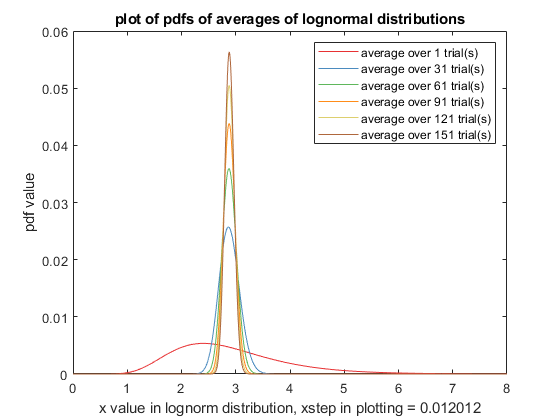

lognorm_M = 1;
lognorm_S = 0.35;

steps_x_space = 1000;
xstep = 12 / (steps_x_space-1);
x = linspace(0, 12 ,steps_x_space);

lognorm_pdf = lognpdf(x,lognorm_M, lognorm_S);

observing_intervals = 1:30:151;

Colors = linspecer(length(observing_intervals));

binned_pdfs = zeros(length(observing_intervals), steps_x_space);

figure

for intervals_index = 1:length(observing_intervals)
    
    intervals = observing_intervals(intervals_index);
    
    convolved_pdf = lognorm_pdf;
    
    for repeat = 2:intervals
        convolved_pdf = conv(convolved_pdf, lognorm_pdf);
    end
    
    for i = 1:(steps_x_space-intervals)
        
        binned_pdfs(intervals_index, i) = sum(convolved_pdf((i-1)*intervals+1:i*intervals))*xstep^intervals;
        
    end
    
    plot(x, binned_pdfs(intervals_index, :), 'Color', Colors(intervals_index, :))
    hold on
    
end

labels = cell(1,length(observing_intervals));
for i = 1:length(observing_intervals)
    string = ['average over ' num2str(observing_intervals(i)) ' trial(s)'];
    labels{i} = string;
end

legend(labels)
title('plot of pdfs of averages of lognormal distributions')
xlabel(['x value in lognorm distribution, xstep in plotting = ' num2str(xstep)])
ylabel('pdf value')
xlim([0,8])

B) Discuss how the shape changes. Does it approach a Gaussian distribution? If yes, after how many intervals?

As the number of intervals increases, the distribution appears to becomes less skewed. The mean moves up due to the long right tail of the lognormal pdf. Interestingly, sums of lognormal distributions do not necessarily convege to a normal distribution. Plotting the above with log y axes, we see that the even with many averages, the two tails of the lognormal distribution fall off very differently, much differently from the symmetric normal distribution. In fact, increasing the number of averages to the point that increased precision is required by matlab, the tails are still quite different. 

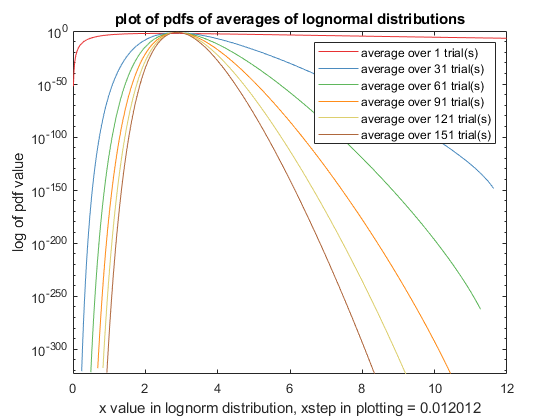

figure

for i = 1:length(binned_pdfs(:, 1))
    
    plot(x, binned_pdfs(i, :), 'Color', Colors(i, :))
    hold on
    
end

labels = cell(1,length(observing_intervals));
for i = 1:length(observing_intervals)
    string = ['average over ' num2str(observing_intervals(i)) ' trial(s)'];
    labels{i} = string;
end

legend(labels)
title('plot of pdfs of averages of lognormal distributions')
xlabel(['x value in lognorm distribution, xstep in plotting = ' num2str(xstep)])
ylabel('log of pdf value')
set(gca,'YScale','log')

While the tails look atrocious, it is possible to model a select region close to the mean as a Gaussian. We show how good it looks on a non-log plot and then show how the Gaussian fit fails in the tails using a log x-xaxis. Even on the non-log plot, you can see that the data and the fitted curve start to separate as the tails begin! Also note that increasing from about 150 trials runs into precision issues with matlab. So even at pushing the precision limits of matlab, a Gaussian approximation is probably only valid within 2 or 3 sigma of the mean. 

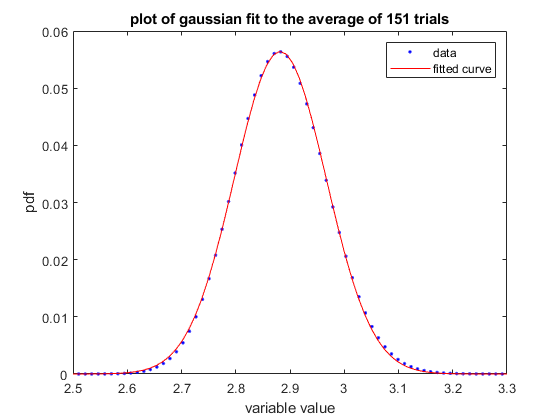

f = fit(x.', binned_pdfs(end, :).', 'gauss1');

figure

plot(f,x,binned_pdfs(end, :))
xlim([2.5,3.3])
title(['plot of gaussian fit to the average of ' num2str(observing_intervals(end)) ' trials'])
xlabel('variable value')
ylabel('pdf')

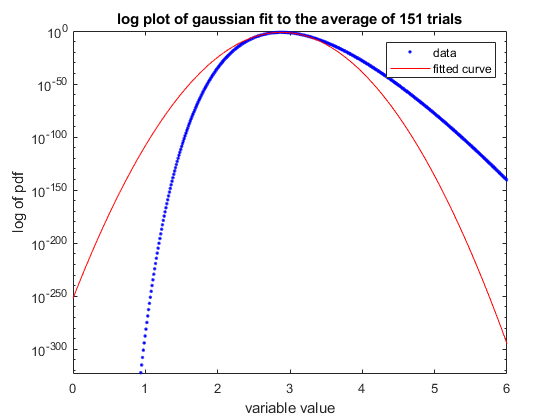

figure

plot(f,x,binned_pdfs(end, :))
xlim([0,6])
title(['log plot of gaussian fit to the average of ' num2str(observing_intervals(end)) ' trials'])
xlabel('variable value')
ylabel('log of pdf')
set(gca,'YScale','log')

From above, given how good the Gaussian fit appeared around the mean, I was worried I was running into issues with convolving too many times. Looking at the convolved pdf, the sum pdf should only be exactly precise for the same interval that the original lognormal was plotted over. This would lead me to believe that after many many convolutions, there could be errors abounding due to the only very small region (of the sum pdf) that is exactly precise. As a consequence, I have decided to do the problem "manually" below. Pulling from various numbers of lognormal distributions and averaging them (all with high numbers of sampling), we can see that they do seem to approach a Gaussian distribution. 

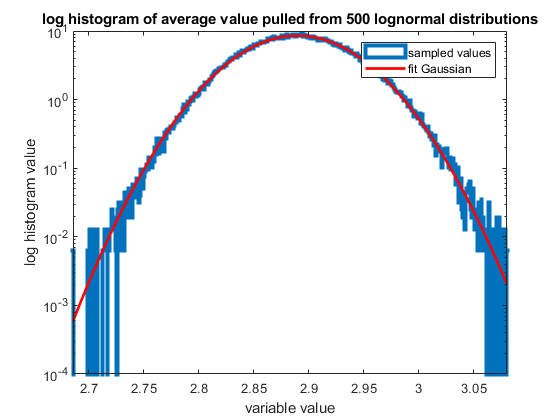

trial_size = 200000;
number_of_averages = 500;

vals = lognrnd(lognorm_M, lognorm_S, number_of_averages, trial_size);

averaged = zeros(1, trial_size);

for j = 1:number_of_averages
    averaged = averaged + vals(j, :);
end

averaged = averaged / number_of_averages;

numbins = 500;
pd = fitdist(averaged', 'Normal');

figure


histogram(averaged,numbins,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
hold on
xlim([min(averaged), max(averaged)])
xl = xlim;
x_hist = linspace(min(averaged), max(averaged), numbins);
plot(x_hist, pdf(pd, x_hist), 'Color', 'red', 'LineWidth',2)
title(['log histogram of average value pulled from ' num2str(number_of_averages) ' lognormal distributions'])
set(gca, 'Yscale', 'Log')
legend({'sampled values', 'fit Gaussian'})
xlabel('variable value')
ylabel('log histogram value')

While this initially appears a good fit, looking at the x-axis, we see that this is only a tiny region around the mean. Additionally, the right side of the Gaussian seems to fall off too steeply while the left side doesn't fall off steep enough. Re-examining our fit to the convolutions over the same range we see the same effect on this scale very close to the mean (below). So, despite valid worries of the precision of the convolution method, actually sampling from lognormal distributions returns similar results: the tails of the Gaussian quickly fail to accurately describe the average of many lognormal distributions. Increasing the number of averages into the hundreds still leaves the gaussian fit lacking once several standard deviations from the mean. If the goal is to have the Gaussian fit be accurate out to 5 sigma, it seems that thousands of trials, if not more, would have to be averaged together for the lognormal distribution to approach the Gaussian. 

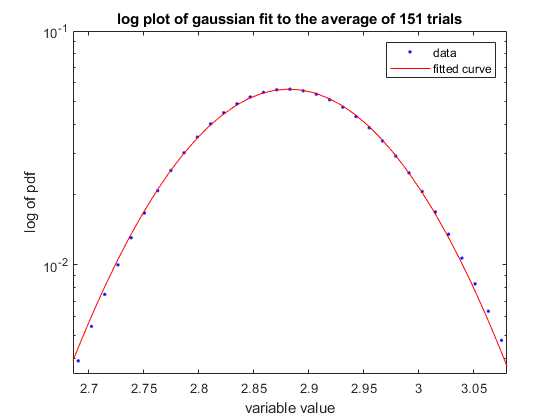

figure

plot(f,x,binned_pdfs(end, :))
title(['log plot of gaussian fit to the average of ' num2str(observing_intervals(end)) ' trials'])
xlabel('variable value')
ylabel('log of pdf')
set(gca,'YScale','log')
xlim(xl)

## Problem 3

The discovery of optical/infra-red counterparts of Neutron star mergers  initially detected with gravity-waves is one of the great discoverys in  the last few years ([wikipedia](https://en.wikipedia.org/wiki/GW170817), [scientific paper](https://arxiv.org/abs/1710.05833)), and has ushered in the age of "multi-messenger astrophysics." The  science that can be done by matching a gravity-wave signal (directly  measures the mass of the neutron stars and their distance) with the  optical emisson (redshift, nuclear astrophysics of the resulting  explosion) is *staggering*. Lots of science from how the heaviest elements are formed to constraints on Dark Energy.

We're going to explore one of the analysis questions that comes up  when looking for the optical counterparts (a new optical source) of a  gravity wave signal. For this problem let's assume that we are using an  optical telescope with a thermal noise background from the CCD (dark  current, particularly an issue with older CCDs and/or infra-red CCDs).  After flat-fielding, the background appears as a zero-mean Gaussian with constant width over the image.

**Version 1**

You have an alert from [LIGO](https://www.ligo.caltech.edu) that is also seen in with the X-ray/ultra-violet satellite [SWIFT](https://swift.gsfc.nasa.gov). SWIFT gives you a very precise location, so you take an image of that  part of the sky. But because of SWIFT's accuracy, you know which pixel  in your image to look for a counterpart in.

A) From looking at all the other pixels in your image, you can  measure the width of the background Gaussian distribution X (pick  something). Assuming you see a signal of strength Y (pick a  floating-point number; optical CCDs are not sensitive enough to count  photons so the readings are floating point brightnesses, not integer  photons). Calculate the significance of your detection. Can you claim a  discovery (traditionally 5-sigma or more)?

Assume the background Gaussian distribution width is 27.3 (in appropriate units of brightness, henceforth referred to as camera brightness units or CBU). Suppose we see a signal of strenght 112.6 CBU and want to check the significance of this measurement. The probability of measuring this many CBUs or more from just the background is:

format long
prob_from_background = 1- normcdf(112.6, 0, 27.3)

prob_from_background =      1.857365018753665e-05


As our background distribution is Gaussian we can get the sigma value by dividing 112.6 by 27.3 to see that we have a sigma value of 4.125, but we can also verify this with norminv():

sigma_val = norminv(1-prob_from_background)

sigma_val =    4.124542124542146


As this is less than 5, we cannot claim a discovery.

**Version 2**

You have an alert from LIGO, but no associated detection from SWIFT. This  could be because it is a black hole-black hole merger, a black  hole-neutron star merger (neither seem to emit X-rays or UV light), or  it could because SWIFT was indisposed at the time (wrong side of the  earth in its orbit). Whatever the cause, you know what region of the sky to look in, but not which pixel.

B) If you have to look for a signal in 10k pixels, what is the probability distribution of your background? (*Clearly* state the statistical question, then turn that into math using your background distribution from part 1 of this problem.)

The probability distribution for a single pixel was a Gaussian with mean 0 and standard deviation 27.3. I am assuming that flat fielding allows for negative values (saying it is gaussian with mean zero seems to allow this too, just want to be explicit). The probability distribution of the background is now a multivariate probability distribution. Specifically it is the product of 10,000 independent Gaussian variables, all with their own respective pixel count value. They all have the same mean and standard deviation though (zero and 27.3 respectively). The question now becomes what is the probability that at least one of these 10k pixels has a value of 112.6. This is further expanded upon in part c

C) Taking your brightest candidate signal from the region (assume it  has the same signal as in part 1), calculate the significance of your  detection.

The significance of the data in version 1 is now reworded as: what is the probability in all 10k pixels that we would observe at least one pixel of that count or larger from just the background. This is one minus the probability that all of the 10k pixel values would be less than the observed 112.6. For a single pixel, the probability that the signal there (from just the backround) is at most 112.6 is given by the normcdf(112.6, mean = 0, std = 27.3). So for all 10k pixels, the probability they are all less than 112.6 is just this value to the 10k power. Then to find the probability we would observe at least one of at least 112.6 CBU, we just take 1 minus that probability. As expected, this reduces the significance of measuing a single pixel in the 10k as having a value of 112.6. In fact, as shown below, if there is no source, we expect to measure a signal of at least 112.6 from at least one pixel almost 17% of the time!

one_pixel_prob_atmost_val = normcdf(112.6, 0, 27.3)

one_pixel_prob_atmost_val =    0.999981426349812


prob_all_pixels_atmost_val = one_pixel_prob_atmost_val^(10000)

prob_all_pixels_atmost_val =    0.830490966808306


prob_at_least_1_pixel_atleast_val = 1 - prob_all_pixels_atmost_val

prob_at_least_1_pixel_atleast_val =    0.169509033191694


sigma_val = norminv(1 - prob_at_least_1_pixel_atleast_val)

sigma_val =    0.956107222151517


## Problem 4

The statistical issue we were exploring in the previous problem is called a **trials factor** (sometimes known as a look-elsewhere effect). This is an important  effect, as if you search through a million locations, you would expect  to se ~1 one in a million event. However, it is also often over  estimated how big an impact this makes on the sensitivity of a search.  So in this part of the lab we are going to invert the problem.

Let us again assume we have a Gaussian background (same parameters as Problem 3).

A) Calculate the signal required for a 5-sigma detection in Version 1

Using normcdf(val, mean, std) and norminv(prob, mean, std) we can first find the probability of a 5-sigma detection and then find the associated value for a single pixel's background. Again, because the background is Gaussian with a mean of 0, we can also just look at 5 times the associated sigma value, but it's nice to have a double check:

prob_of_5_sigma = 1 - normcdf(5)

prob_of_5_sigma =      2.866515719235352e-07


val_for_5_sigma = norminv(1-prob_of_5_sigma, 0, 27.3)

val_for_5_sigma =      1.364999999991858e+02


B) Calculate the signal required for a 5-sigma detection in Version 2

Recall that the probability that we measure at least one pixel of a given value is one minus the probability that all the pixels are less than that value. The signal required for a 5-sigma detection in Version 2 is the same as saying what signal value do you have to measure such that the probability that all the pixels are less than that value is one minus the above calculated probability of a 5 sigma event: $1-p_{5\sigma}$. We then take that to 1/10k to find what the probability needs to be for each pixel. Then we calculate the value we have to measure out to to get the single pixel value we need to measure to get a 5-sigma detection in version 2 is 178.8 (code below). 

prob_for_1_pixel = (1 - prob_of_5_sigma)^(1/10000);
val_for_1_pixel = norminv(prob_for_1_pixel, 0, 27.3)

val_for_1_pixel =      1.788296733921422e+02


Note that because the probability of 5 sigma times the trials factor of 10k is still a small number, this is well approximated by saying that for the probability of a trials factor of 10k to be equal to the 5 sigma probability, the probability for a single pixel has to be that probability over 10k:

approx_prob_for_1_pixel = 1 - prob_of_5_sigma/10000;
approx_val_for_1_pixel = norminv(approx_prob_for_1_pixel, 0, 27.3)

approx_val_for_1_pixel =      1.788296733921422e+02


C) Discuss how much brighter the signal must be for discoverey if you have a trials factor of 10k. Looking at your probability distributions, explain why the sensitivity penalty due to a trials factor is so low.

For a trials factor of 10k, the signal only has to be an additionaly ~1.5 standard deviations from the mean of zero. The sensitivity penalty due to trials factors is so low because of two reasons. One: the probability for a 5-sigma detection is very small. A 5-sigma detection is already an incredibly rare event, this means that the probability of getting more than one from the background is vanishingly small. We are already far out in the tail of the Gaussian distribution. This leads into point two: the tail of the gaussian distribution falls off very quickly. Moving from the 5-sigma detection probability for no trials factor to one with a trials factor doesn't require moving very far. If you are already at 5 sigma, very small increases in the value of interest very drastically decrease the probability of a value larger than that being pulled from a Gaussian distribution. As a consequence, even with large trials factors, the candidate value required does not increase by as much. See answer to D) for a plot of the value required for a single measurement with trials factors plotted on a log x axis. 

D) If you changed the trials factor significantly (orders of  magnitude), how large is the effect on your 5-sigma sensitivity threshold?

Below I have plotted as a function of the log base 10 of the trials factor, the value needed for a 5-sigma sensitivity. 10k is the same as the point with 4 on the x-axis. 

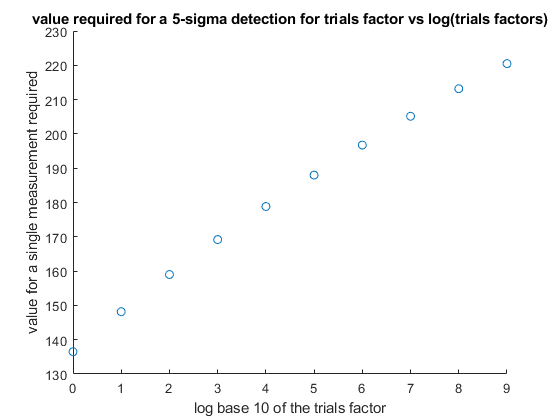

format long

powers = 0:1:9;
trials_factors = 10.^powers;
probs_for_1_pixel = (1 - prob_of_5_sigma).^(1./trials_factors);
vals_for_1_pixel = norminv(probs_for_1_pixel, 0, 27.3);
figure;
scatter(powers, vals_for_1_pixel)
title('value required for a 5-sigma detection for trials factor vs log(trials factors)')
ylabel('value for a single measurement required')
xlabel('log base 10 of the trials factor')

I selectively stopped at a trials factor of $10^9$, because for a trials factor of $10^{10}$ , to get a non-infinite value would require increased precision. While not exactly lying along a line, the increase in the value required to have a 5-sigma detection increases roughly linearly between trials factors of 1 and $10^9$. Fitting a  line to the data we see that the value required for a 5-sigma detection goes up by around 9.8 (0.36 of a standard deviation of a single detection) for each power of ten of the trials factor. Note that this line isn't a great fit, particularly for larger values where it seems to downturn more. 

X = powers';
b = X\(vals_for_1_pixel - vals_for_1_pixel(1))'

b =    9.799255903858420


Extra credit: If you had a different distribution shape  (non-Gaussian), how would that affect the sensitivity penalty of many trials? Clearly explain.

If the background distribution had a different shape, the sensitivity penalty of many trials would be different. For this exact problem (but with a different distribution than Gaussian) the important part of the distribution would be the right tail. Essentially the sensitivity penalty forces you to go further out in the right tail of the distribution to reduce the probability of the single event, keeping the probability over all the trial the same. If the tail of the distribution falls off slower than a gaussian's tail, the penalty would be larger as you would have to move further along the tail to reduce the probability to the same value. The opposite of this is true if the tail falls off slower than a gaussian's right tail. The code would only change once you get to taking the norminv(probability needed for a single pixel so the probability for all of them matches the 5 sigma detection probability). Just replace norminv() with the inverse of whatever the probability distribution of the background is now. 